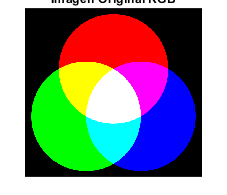

%Read RGB Image
close all
clear all

%Actividad 1
figure (1)
imagen= imread('Image RGB.png');
imshow(imagen)
title('Imagen Original RGB')

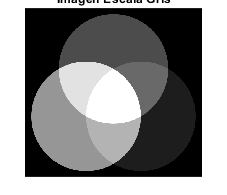


%Actividad 2
figure (2) 
I=rgb2gray(imagen);
imshow(I)
title('Imagen Escala Gris')

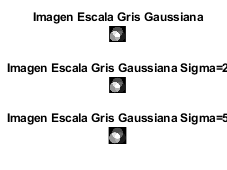


%Actividad 3
figure (3)
B=imgaussfilt(I);
subplot( 3, 1, 1)
imshow(B)
title('Imagen Escala Gris Gaussiana')

C=imgaussfilt(I, 2);
subplot( 3, 1, 2)
imshow(C)
title('Imagen Escala Gris Gaussiana Sigma=2')

D=imgaussfilt(I, 5);
subplot( 3, 1, 3)
imshow(D)
title('Imagen Escala Gris Gaussiana Sigma=5')

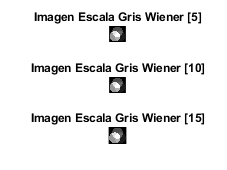


%Actividad 4
figure (4)
J=wiener2(I,[5 5]);
subplot( 3, 1, 1)
imshow(J)
title('Imagen Escala Gris Wiener [5]')

G=wiener2(I,[10 10]);
subplot( 3, 1, 2)
imshow(G)
title('Imagen Escala Gris Wiener [10]')

H=wiener2(I,[15 15]);
subplot( 3, 1, 3)
imshow(H)
title('Imagen Escala Gris Wiener [15]')

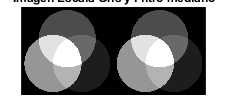


%Actividad 5
figure (5)
I=rgb2gray(imagen);
%imshow(I)


L=medfilt2(I);
%imshow(L)
montage({I, L})
title('Imagen Escala Gris y Filtro mediano')

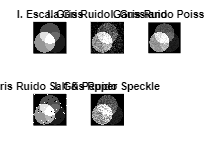


%Actividad 6
figure (6)
I=rgb2gray(imagen);
subplot( 2, 3, 1)
imshow(I)
title('I. Escala Gris')

M = imnoise(I,'gaussian');
subplot( 2, 3, 2)
imshow(M)
title('I. Gris Ruido Gaussiano')

N = imnoise(I,'poisson');
subplot( 2, 3, 3)
imshow(N)
title('I. Gris Ruido Poisson')

O = imnoise(I,'salt & pepper');
subplot( 2, 3, 4)
imshow(O)
title('I. Gris Ruido Salt & Pepper')

P = imnoise(I,'speckle');
subplot( 2, 3, 5)
imshow(P)
title('I. Gris Ruido Speckle')

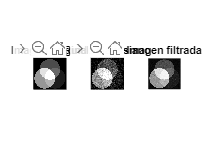


%Actividad 7

 figure(7)
 subplot(1,3,1)
 imshow(I)
 title('Imagen original')  
 subplot(1,3,2)
 imshow(M);
 title('Ruido Gaussiano')
 
 subplot(1,3,3)
 filtro1 = wiener2(M, [5 5]);
 imshow(filtro1)
 title('Imagen filtrada')

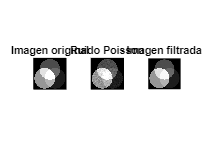

 
 figure(8)
 subplot(1,3,1)
 imshow(I)
 title('Imagen original') 
 
 subplot(1,3,2)
 imshow(N);
 title('Ruido Poisson')
 
 subplot(1,3,3)
 filtro2 = wiener2(N, [10 10]);
 imshow(filtro2)
 title('Imagen filtrada')

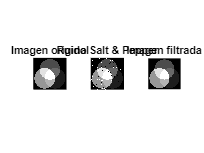

 
 figure(9)
 subplot(1,3,1)
 imshow(I)
 title('Imagen original') 
 
 subplot(1,3,2)
 imshow(O);
 title('Ruido Salt & Pepper')
 
 subplot(1,3,3)
 filtro3 = medfilt2(O);
 imshow(filtro3)
 title('Imagen filtrada')

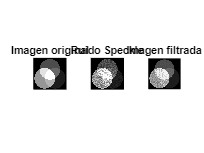


 
figure(10)
subplot(1,3,1)
imshow(I)
title('Imagen original') 

subplot(1,3,2)
imshow(P);
title('Ruido Speckle')

subplot(1,3,3)
filtro4 = wiener2(P, [5 5]);
imshow(filtro4)
title('Imagen filtrada')